# HW3_2_2

First remove all open background.

close all;
clear;
clc;

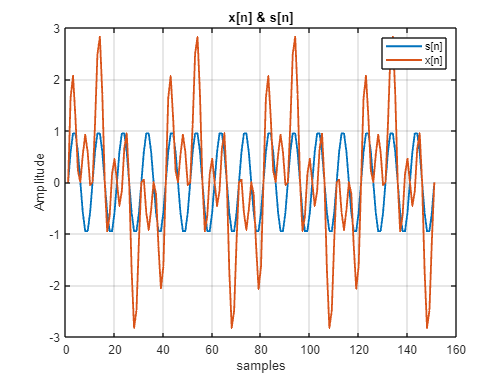

n = (0: 150);
s = sin(0.2*pi*n);
v = sin(0.05*pi*n) + sin(0.35*pi*n);

x = s + v;

figure('Name', 'x[n] & s[n]');
plot(s, 'LineWidth', 1.5); hold on;
plot(x, 'LineWidth', 1.5); hold off;
legend('s[n]', 'x[n]')
ylim([-3, 3])
xlabel('samples');
ylabel('Amplitude');
title('x[n] & s[n]');
grid on;

Hamming window & filter

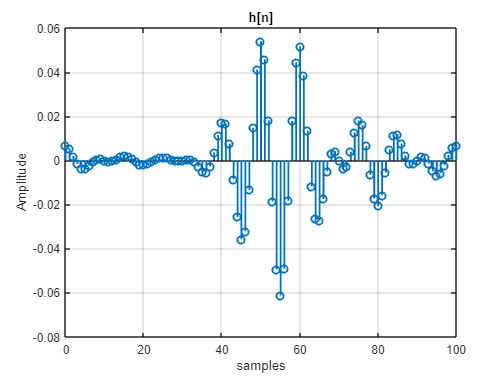

M = 100;
n1 = 0: M;
w = 0.54 - 0.46 * sin(2 * pi * n1 / M);
h = w.*(0.25*sinc(0.25*(n1-M/2))-0.15*sinc(0.15*(n1-M/2)));

figure('Name', 'h[n]');
stem(n1, h, 'LineWidth', 1.5);
xlabel('samples');
ylabel('Amplitude');
title('h[n]');
grid on;

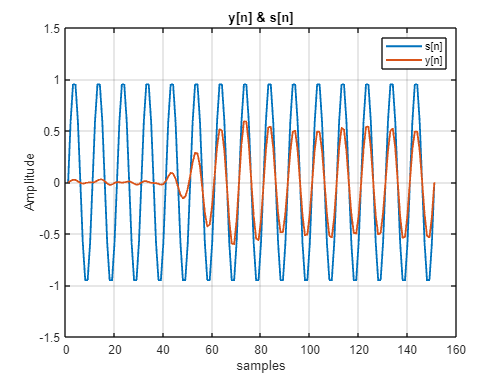

y = filter(h, 1, x);

figure('Name', 'y[n]');
plot(s, 'LineWidth', 1.5); hold on;
plot(y, 'LineWidth', 1.5); hold off;
legend('s[n]', 'y[n]')
ylim([-1.5, 1.5])
xlabel('samples');
ylabel('Amplitude');
title('y[n] & s[n]');
grid on;

Now load the filter that generate before.

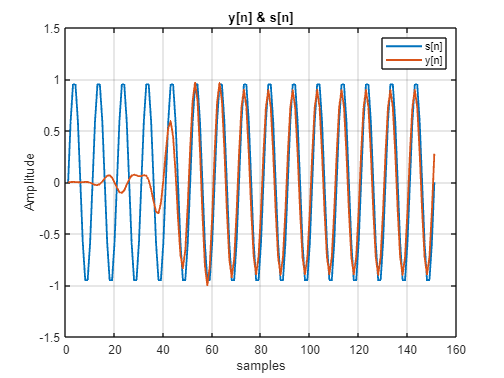

coef = load('coefFilterHW3.mat').Num;

y = filter(coef, 1, x);

figure('Name', 'y[n]');
plot(s, 'LineWidth', 1.5); hold on;
plot(y, 'LineWidth', 1.5); hold off;
legend('s[n]', 'y[n]')
ylim([-1.5, 1.5])
xlabel('samples');
ylabel('Amplitude');
title('y[n] & s[n]');
grid on;